F = F(:);
%CREATINNG THE NORMALIZED HISTOGRAM
clf;
hold on;
LegHandles = []; LegText = {};



[CdfF,CdfX] = ecdf(F,'Function','cdf'); 
BinInfo.rule = 1;
[~,BinEdge] = internal.stats.histbins(F,[],[],BinInfo,CdfF,CdfX);
[BinHeight,BinCenter] = ecdfhist(CdfF,CdfX,'edges',BinEdge);
hLine = bar(BinCenter,BinHeight,'hist');
set(hLine,'FaceColor','none','EdgeColor',[0.333333 0 0.666667],...
    'LineStyle','-', 'LineWidth',1);
xlabel('Data');
ylabel('Density')
LegHandles(end+1) = hLine;
LegText{end+1} = 'Data';


XLim = get(gca,'XLim');
XLim = XLim + [-1 1] * 0.01 * diff(XLim);
XContinuous = linspace(XLim(1),XLim(2),100);
XIncr = max(1,floor((XLim(2)-XLim(1))/100));
XDiscrete = floor(XLim(1)):XIncr:ceil(XLim(2));

%CREATING ERROR BARS

normalizedelements=[0.005 0.02 0.05 0.125 0.1 0.09 0.05 0.04 0.01 0.01];
elements=200*normalizedelements;
bincenters= 3:2:21;
err=sqrt(elements)/200;
bar(bincenters, normalizedelements);

errorbar(bincenters,normalizedelements, err,'*');
%POISSON
pd1 = fitdist(F, 'poisson')

pd1 =   PoissonDistribution

  Poisson distribution
    lambda = 10.9   [10.2529, 11.5471]


XGrid = XDiscrete;
YPlot = pdf(pd1,XGrid);
hLine = plot(XGrid,YPlot,'Color',[1 0 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','+', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'poisson';
%NORMAL

pd2 = fitdist(F, 'normal')

pd2 =   NormalDistribution

  Normal distribution
       mu =    10.9   [10.1824, 11.6176]
    sigma = 3.61674   [3.17552, 4.20148]


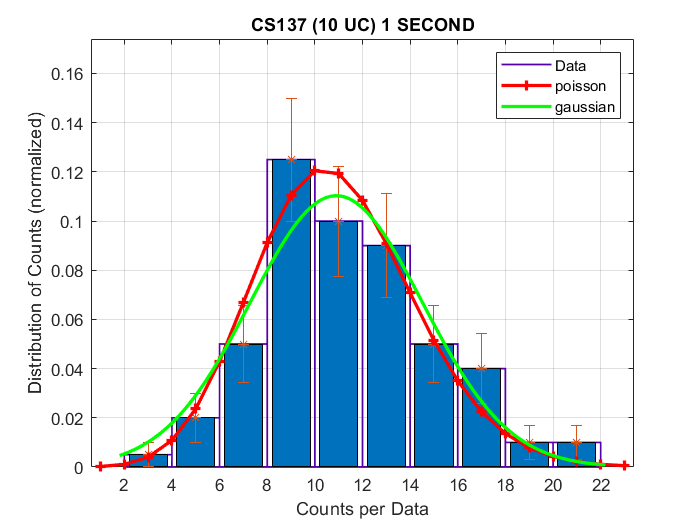

XGrid = XContinuous;
YPlot = pdf(pd2,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0 1 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'gaussian';

grid on;
box on;
hold off;


hLegend = legend(LegHandles,LegText,'Orientation', 'vertical', 'FontSize', 9, 'Location', 'northeast');
set(hLegend,'Interpreter','none');

xlim([0.6 23.4])
ylim([0 0.174])

title('CS137 (10 UC) 1 SECOND')
xlabel('Counts per Data')
ylabel('Distribution of Counts (normalized)')